# Homework 3

requirements:

- Phase margin must be at least $60\;\degree$

- The settling time of a step response within a $\pm 2%$ band must be less than 3 seconds, while

- the steady state error of the system in the case of a unit ramp input should not exceed 0.1.

- the bandwidth of the system not exceed 15 rad/s

clearvars, clc, clear all


$$G\left(s\right)=\frac{50\left(s+15\right)}{s^4 +36s^3 +484s^2 +3280s}$$


num = 50 * [1 15];
den = [1 36 484 3280 0];
G = tf(num, den);
G


G =
 
            50 s + 750
  -------------------------------
  s^4 + 36 s^3 + 484 s^2 + 3280 s
 
Continuous-time transfer function.


Gzpk = zpk(G)


Gzpk =
 
          50 (s+15)
  --------------------------
  s (s+20) (s^2 + 16s + 164)
 
Continuous-time zero/pole/gain model.


 the steady state error is calculated in terms of the ramp error constant $K_v$ and thus a required value of is established:


$$e_{\textrm{ss}} =\frac{A}{K_v }\le 0\ldotp 1$$



$$K_v \ge 10$$


It is important to realize that this value represents the required $K_v$ .

The actual $K_v$ will depend on the gain chosen by the designer. If for instance the designer chooses to start his design by selecting $D_c \left(s\right)=1$and he/she then calculates the actual $K_v$. Here $K_v =\frac{50\times 15}{20\times 164}=\frac{75}{328}$, is small by a factor of 43.73. So we can put a gain $K_1 =44$ in series with the plant.

K1 = 44

K1 = 44

T = feedback(K1*G,1)


T =
 
              2200 s + 33000
  ---------------------------------------
  s^4 + 36 s^3 + 484 s^2 + 5480 s + 33000
 
Continuous-time transfer function.


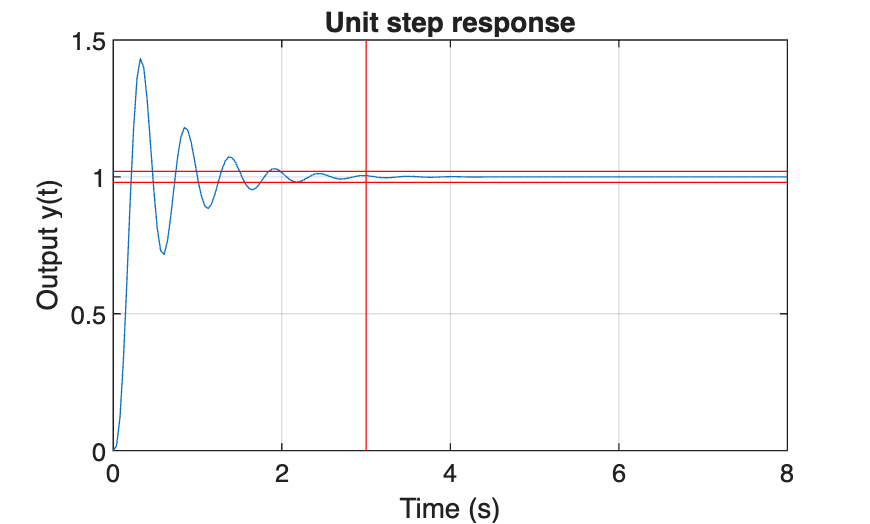

tt = linspace(0.0,8.0,200);
y = step(T,tt);
figure(1)
plot(tt,y)
hold on
plot([tt(1), tt(end)],[1.02, 1.02],'r')
plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([3,3],[0,1.5],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')

Now we plot the Bode diagram of the uncompensated system.

figure(2)
omega = logspace(0,2,400);
[mag1,phase1] = bode(K1*G,omega);
mag1 = squeeze(mag1);
phase1 = squeeze(phase1);
subplot(2,1,1),semilogx(omega,20*log10(mag1))
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
hold on
grid on
title('Plant (open loop) transfer function bode diagram')
subplot(2,1,2),semilogx(omega,phase1)
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
hold on
grid on
[Gm,Pm,omegcp,omegcg] = margin(K1*G);
dBGm = 20*log10(Gm);
disp(['System phase margin (degrees): ',num2str(Pm)])

System phase margin (degrees): 27.24


disp(['System cross over angular frequency (rad/s): ',num2str(omegcg)])

System cross over angular frequency (rad/s): 10.2164


disp(['System gain margin (dB): ',num2str(dBGm)])

System gain margin (dB): 4.6566


disp(['System Phase Crossover Frequency (rad/s):',num2str(omegcp)])

System Phase Crossover Frequency (rad/s):13.9847


We therefore need to turn to step 3: Determine the frequency where the phase margin requirement would be satisfied if the magnitude curve crossed the 0 dB line at this frequency, ${\omega_c }^{\prime }$,(Allow for $5\degree$phase lag from the

phase-lag compensator when determining the new crossoverfrequency.)

Since the phase margin of the gain we need is $60\degree$, It is suggested that we add a measure of safety of 5 degree, so  I decided to start off my design iteration with the value of ${\omega_c }^{\prime }$ at the which PM is $-180\degree +60\degree +5\degree =-115\degree$

From Franklin Eq.6-40


$$\alpha =\frac{1-\sin \;\phi_{\max } }{1+\sin \phi_{\max } }$$


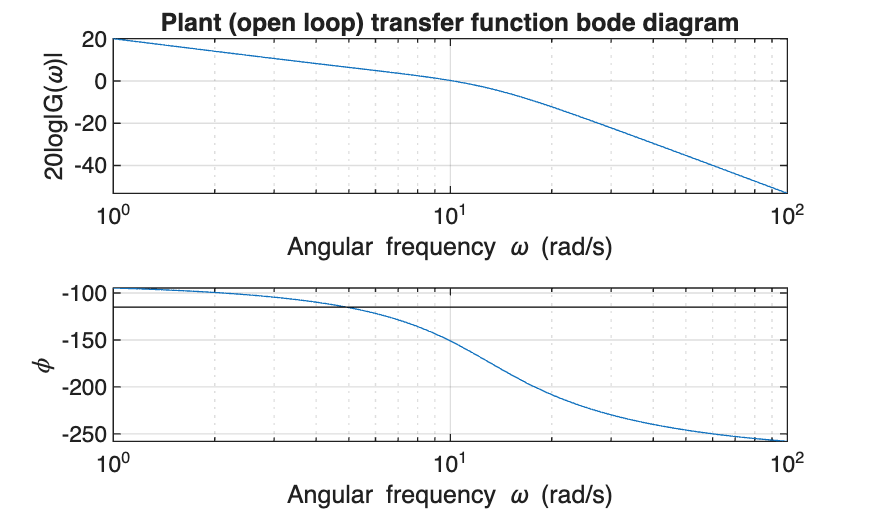

target_phase = -115;
figure(2)
subplot(2,1,2),semilogx([omega(1),omega(end)],[target_phase,target_phase],'k')

wc_prime = interp1(phase1, omega, target_phase);
T_I = 10/wc_prime

T_I = 2.0357

disp(['omega_c_prime at target PM is: ',num2str(wc_prime)])

omega_c_prime at target PM is: 4.9124


mag_wc_prime = interp1(omega,mag1,wc_prime);
attenuation_dB = -20 * log10(mag_wc_prime);
disp(['necessary attenuation at \omega_c_prime  to ensure curve crosses 0 dB is : ',num2str(attenuation_dB)])

necessary attenuation at \omega_c_prime  to ensure curve crosses 0 dB is : -6.6058


alpha = mag_wc_prime

alpha = 2.1394

From the figure, the ${\omega_c }^{\prime }$ is read by 4.912 rad/s, 


$$z=\frac{1}{T_I }=\frac{{w_c }^{\prime } }{10}=0\ldotp 491,T_I =2\ldotp 0357$$


When ${w_c }^{\prime } =4\ldotp 912$, $20\log \left(G\left(\omega \right)\right)=$ -6.6058

$\textrm{attentuation}=-20\textrm{log10}\left(\alpha \;\right)\Rightarrow \alpha =$2.1394

and then the compensator is calculated as: $D_C =\frac{T_I s+1}{\alpha \;T_I s+1},\alpha >1$

Dc = tf([T_I, 1],[alpha*T_I, 1])


Dc =
 
  2.036 s + 1
  -----------
  4.355 s + 1
 
Continuous-time transfer function.


disp("Lag compensator zero = -"+num2str(1/T_I)+"rad/s")

Lag compensator zero = -0.49124rad/s


disp("Lag compensator pole = -"+num2str(1/(alpha*T_I))+"rad/s")

Lag compensator pole = -0.22962rad/s


disp('Compensated loop transfer function:')

Compensated loop transfer function:


Gt = Dc*K1*G


Gt =
 
               4478 s^2 + 6.938e04 s + 33000
  --------------------------------------------------------
  4.355 s^5 + 157.8 s^4 + 2144 s^3 + 1.477e04 s^2 + 3280 s
 
Continuous-time transfer function.


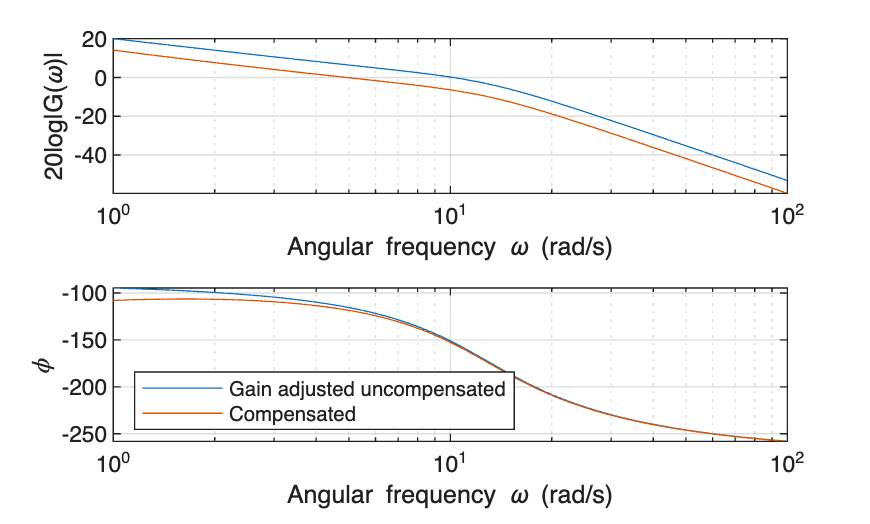


figure(3)
title('Loop transfer functions Bode diagrams')
[mag2,phase2] = bode(Gt,omega);
mag2 = squeeze(mag2);
phase2 = squeeze(phase2);
subplot(2,1,1)
semilogx(omega,20*log10(mag1))
hold on
semilogx(omega,20*log10(mag2))
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
subplot(2,1,2)
semilogx(omega,phase1)
hold on
semilogx(omega,phase2)
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
legend('Gain adjusted uncompensated','Compensated','Location','southwest')


[Gm,Pm,omegcp,omegcg] = margin(Gt);
dBGm = 20*log10(Gm);
disp(['Compensated system phase margin (degrees): ',num2str(Pm)])

Compensated system phase margin (degrees): 61.8577


disp(['Compensated system cross over angular frequency (rad/s): ',...
num2str(omegcg)])

Compensated system cross over angular frequency (rad/s): 4.9325


disp(['Compensated system gain margin (dB): ',num2str(dBGm)])

Compensated system gain margin (dB): 11.0383


disp(['Compensated system gain margin cross over angular frequency (rad/s): '...
,num2str(omegcp)])

Compensated system gain margin cross over angular frequency (rad/s): 13.8149


disp("Compensated system transfer function"+...
"(i.e., the closed loop transfer function):")

Compensated system transfer function(i.e., the closed loop transfer function):


T2 = feedback(Gt,1)


T2 =
 
                     4478 s^2 + 6.938e04 s + 33000
  --------------------------------------------------------------------
  4.355 s^5 + 157.8 s^4 + 2144 s^3 + 1.925e04 s^2 + 7.266e04 s + 33000
 
Continuous-time transfer function.


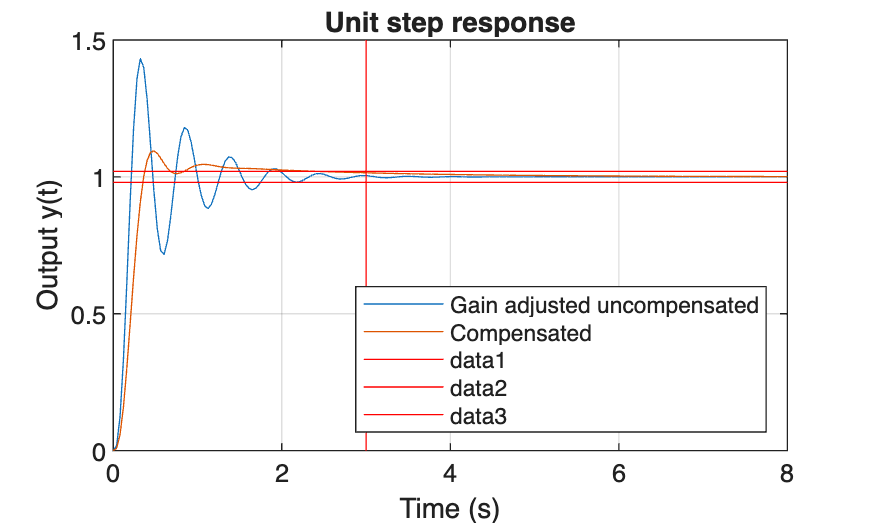

y2 = step(T2,tt);
figure(4)
plot(tt,y,tt,y2)
legend('Gain adjusted uncompensated','Compensated','location','southeast')
hold on
plot([tt(1), tt(end)],[1.02, 1.02],'r')
plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([3, 3],[0.0, 1.5],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')
hold off

% --- 带宽观测部分 ---
BW = bandwidth(T2); % 计算闭环系统的 3dB 带宽
disp(['Compensated system bandwidth (rad/s): ', num2str(BW)])

Compensated system bandwidth (rad/s): 10.732



% 验证带宽限制是否满足要求 (15 rad/s)
if BW <= 15
    disp('Result: Bandwidth requirement (< 15 rad/s) is SATISFIED.')
else
    disp('Result: Bandwidth requirement (< 15 rad/s) is VIOLATED.')
end

Result: Bandwidth requirement (< 15 rad/s) is SATISFIED.


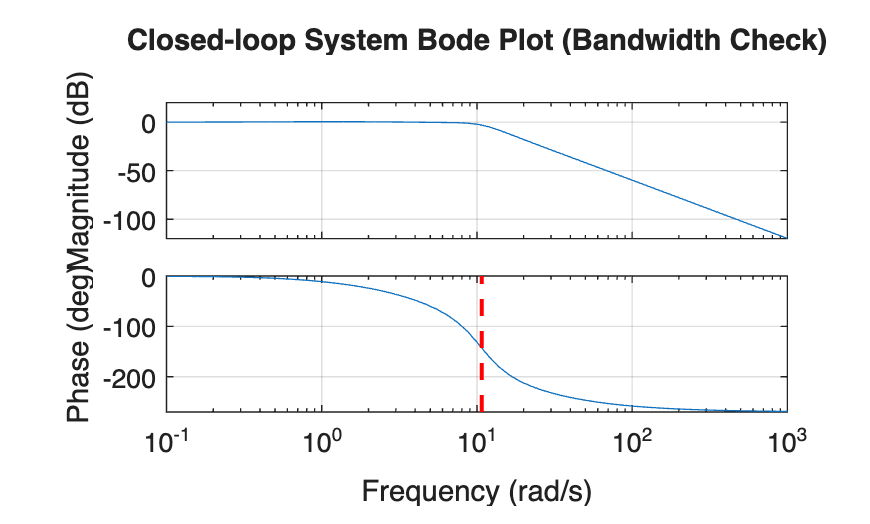


% 在波特图中可视化带宽 (可选)
figure(5)
bode(T2)
grid on
title('Closed-loop System Bode Plot (Bandwidth Check)')
hold on
% 画出 -3dB 的参考线
current_axis = axis;
plot([BW, BW], [current_axis(3), 0], 'r--', 'LineWidth', 1.5)
text(BW, -5, [' \leftarrow BW = ', num2str(BW), ' rad/s'], 'FontSize', 10, 'Color', 'r')